# HW02 - Problem 2: Scaling

For Problem 2 consider an MSD system.  The mass is towed by a winch that generates a force$f(t)$ and a has a DC motor on the front axis that generates a force  $f_m(t)$.

The Plant inputs are therefore: $u_1 :=  armature\ voltage\  [V];\quad u_2:= towing\ force\ f\ [N]$. 

We consider as outputs: $y_1 := x\ axis\ Position\  [m];\quad y_2:= armature\ current\ [A]$

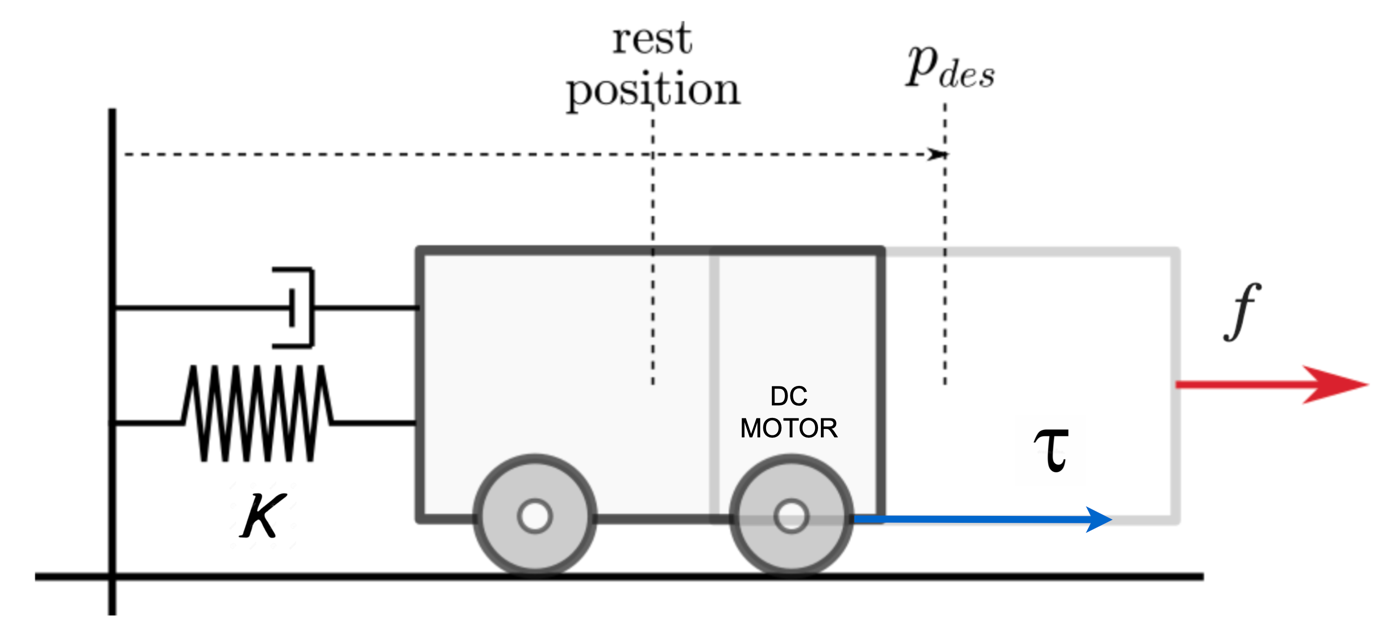

Motor parameter are taken from [this paper](https://www.researchgate.net/publication/272102820_Parameters_Identification_of_a_Permanent_Magnet_DC_Motor/figures?lo=1) for realistic quantities. Every other parameter was chosen in order to "justify" the presence of two inputs.

#### System Parameters

%MSD Parameters
% system parameters
m  = 50; % mass
mu = 2; % "low" viscous friction coefficient
k  = 20; % spring coefficient


% Motor Parameters from:
% https://www.researchgate.net/publication/272102820_Parameters_Identification_of_a_Permanent_Magnet_DC_Motor/figures?lo=1

% Motor Parameters
Kt = 1.835;
Ke = 1.835;
L = 0.104;
R = 3.05;

% Wheel Radius
r = 0.35;

### Goal:

We want to bring a mass m = 50 Kg at the desired position $r_1 =1\;m$, countering the elastic force generated by a spring with elastic coefficient K = 20 N/M  ($F_e =-K\;r_1 =20\;N$). 

We also want to assign a reference $r_2 =2\;A$ to the current so that the motor can operate safely  (maximum armature current is 3 A according to motor datasheet).

With this choice of parameters, the motor can generate a maximum force $f_{m,\ max} = K_tr_2/ r_{wheel} \approx 10.5 N$ and $u_2$ ("the winch") must provide the residula force necessary to conter the elastic force $F_{e\;} =20\;N$. However that too will be limited by $f_{max} = 15 N, so that only using both inputs the elastic force can be "won".

### Dynamical System Definition

% Dynamics' Matrices 
A = [0 1 0;
    -k/m -mu/m Kt/(m*r);
    0 -Ke/L -R/L];

B = [0 0; 0 1/m; 1/(L*r) 0];
C = [1 0 0; 0 0 1];
D = [0 0; 0 0];

s = tf('s');

% State Space Representation
G_ss = ss(A,B,C,D);
G_ss.u = ['V(t)';'f(t)'];
G_ss.y = ['x(t)';'i(t)'];


[N1,D1] = ss2tf(A,B,C,D,1);
[N2,D2] = ss2tf(A,B,C,D,2);

%G11 = (Kt/r^2)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G11 = tf(N1(1,:),D1);

%G12 = (R + L*s)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G12 = tf(N2(1,:),D2);

%G21 = ((m*s^2 + mu*s + k)/r)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G21 = tf(N1(2,:),D1);

%G22 = (-Ke*s)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G22 = tf(N2(2,:),D2);
G = minreal([G11 G12; G21 G22]);

r1 = 1; % 1 Meter Reference (desired position)
r2 = 2; % 2 Ampere Reference (desired operational current)

% Condition number
G0 = freqresp(G,0);
[U,S,V] = svd(G0)

U =    -0.2542   -0.9671
   -0.9671    0.2542


S =     0.9685         0
         0    0.0484


V =    -0.9999    0.0131
   -0.0131   -0.9999


disp(strcat("Condition Number: ", num2str(S(1,1)/S(2,2))))

Condition Number: 20.0263


# AUGMENTED PLANT

From now on, we'll consider this **augmented plant for simulation**. 

We consider as exogenous outputs the references ($w:={\left\lbrack r_1 \;r_2 \right\rbrack }^T$); as performance variables we consider tracking errors and control efforts ($z:={\left\lbrack e_1 \;e_2 \;m_1 \;m_2 \right\rbrack }^T$). For synthesis purposes, this scheme will be expanded adding this ** scaling and performance weghts.**

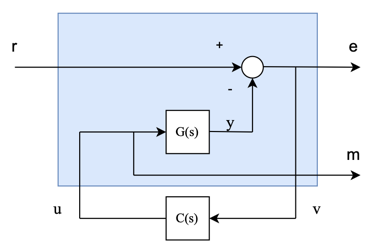

The resulting **simulation augmented plant** is defined below**. **(where each block is 2x2)


$$P_e =\left\lbrack \begin{array}{cc}
I & -G\left(s\right)\\
0 & I\\
\cdots \cdots \cdots  & \cdots \cdots \cdots \\
I & -G\left(s\right)
\end{array}\right\rbrack$$


Pe = [eye(2) -G; zeros(2,2) eye(2); eye(2) -G];

# CASE I: No Scaling, mixsyn(...) synthesis on G

At first let's try to use mixsyn, which automatically builds the augmented plant on the original 2x2 MIMO with the performance weight defined below

% Sensitivity Weight
Ms = 1.01;
B3s = 1.0;
As = 0.01;

ws = (s/Ms+B3s)/(s+B3s*As)*eye(2);

% Control Sensitivity Weight
wu = [1/10 0; 0 1/10];

% Mixed Sensitivty Synthesis
[C1, ~, GAM_unsc] = mixsyn(G, ws,wu,[]);
GAM_unsc

GAM_unsc = 2.4996

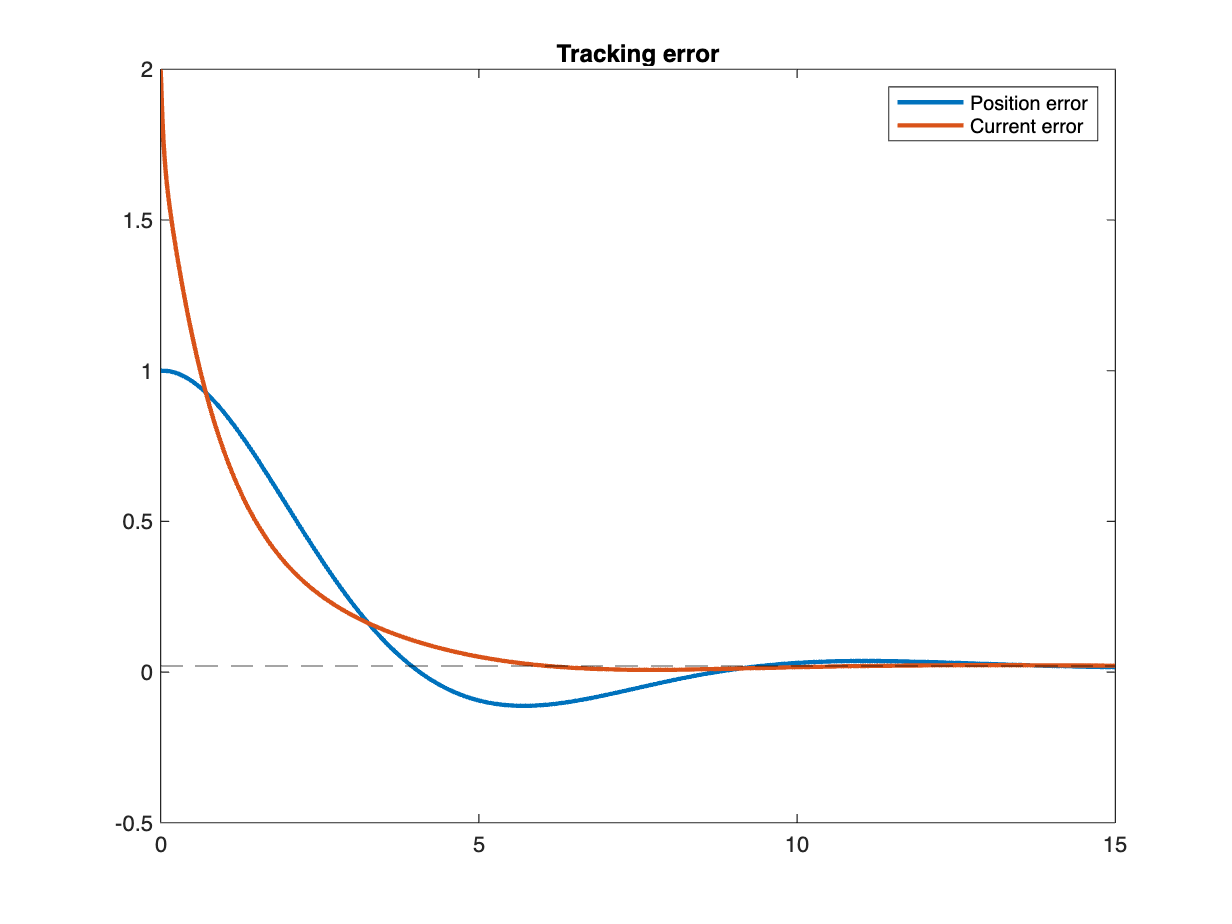

% Simulation time
t = 0:0.01:15;

% References
ref = [ones(1,length(t))*r1;
    ones(1,length(t))*r2];

% Closed Loop with unscaled mixsyn
CLoop_mix_unsc = lft(Pe,C1);

% Simulation mixsyn
[y_uns, t_uns] = lsim(CLoop_mix_unsc, ref, t);

figure()
plot(t_uns, y_uns(:,1),t_uns, y_uns(:,2),'LineWidth',2)
yline(0.02,'k--')
title("Tracking error")
legend("Position error",'Current error')

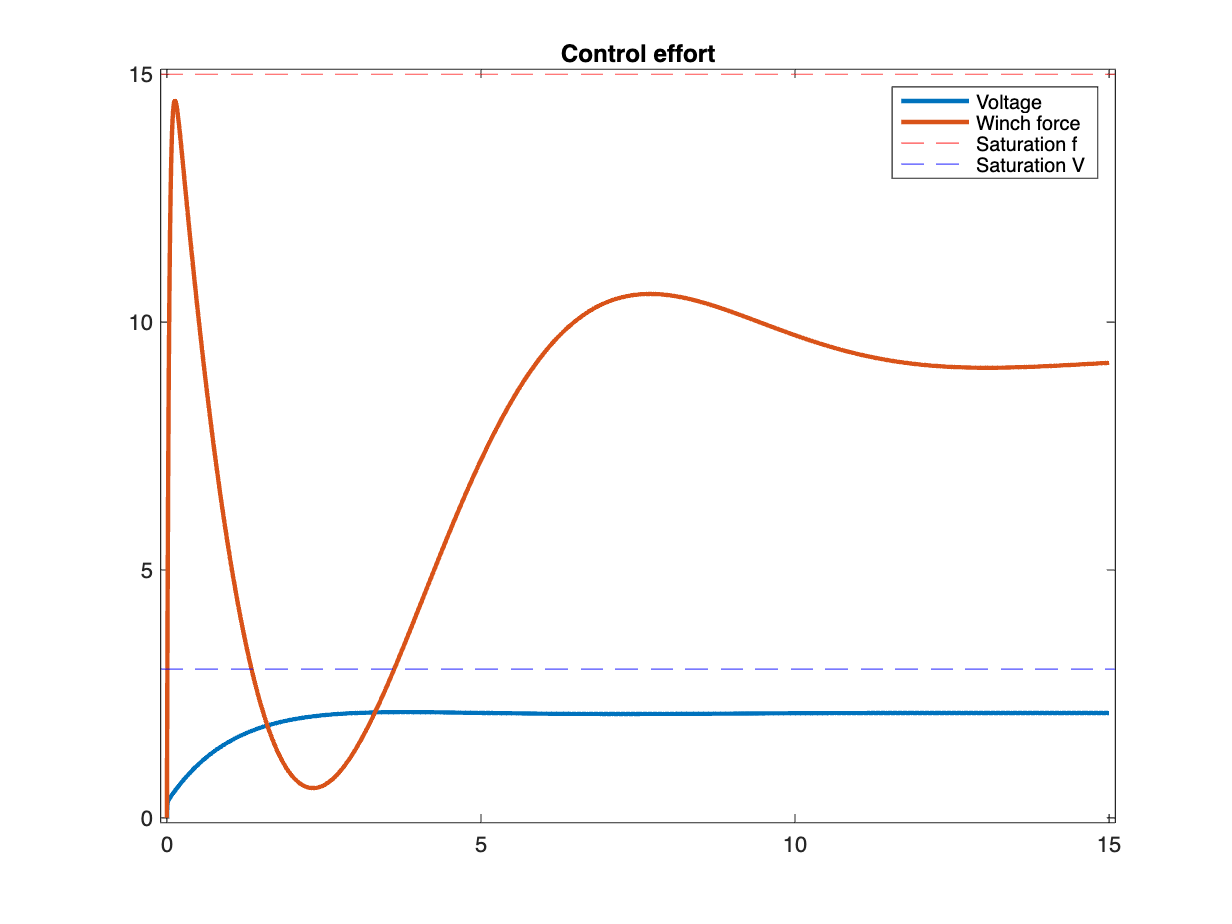

figure()
plot(t_uns, y_uns(:,3),t_uns, y_uns(:,4),'LineWidth',2)
hold on
yline(15, 'r--')
yline(3, 'b--')
xlim([-0.1,15.1])
ylim([-0.1,15.1])
title("Control effort")
legend('Voltage','Winch force','Saturation f','Saturation V','Location','northeast')

Results are more than acceptable. We never reach saturation and the convergence speed is fast enough.

# CASE II: No scaling, hinfsyn(...) on Pe

Let's try to use the augmented plant **with no weights **to see if hinfsyn(...) can sythetize a controller.

opts = hinfsynOptions('Method','Ric','Autoscale','off','Regularize','off');
[C2,CL2,gam] = hinfsyn(Pe,2,2,10,opts);
gam

gam = 1.0000

Vediamo subito che qualcosa non torna perchè per qualsiasi opzione imponiamo, qualsiasi gamTry imponiamo, il gamma restituito è sempre 1. Stampando il sistema ad anello chiuso vediamo dove si genera il problema.

simplify(zpk(minreal(CL2)))

6 states removed.

ans =
 
  From input 1 to output...
       (s+40.23) (s+29.26) (s^2 + 0.1033s + 0.4009) (s^2 + 0.1425s + 0.4074)
   1:  ---------------------------------------------------------------------
       (s+40.23) (s+29.26) (s^2 + 0.1033s + 0.4009) (s^2 + 0.1425s + 0.4074)
 
             1.0596e-12 (s+28.69) (s+0.4126) (s^2 + 0.03096s + 0.4005)
   2:  ---------------------------------------------------------------------
       (s+40.23) (s+29.26) (s^2 + 0.1033s + 0.4009) (s^2 + 0.1425s + 0.4074)
 
        -3.857e-14 (s+29.26) (s+28.69) (s+0.4131) (s^2 + 0.1033s + 0.4009)
   3:  ---------------------------------------------------------------------
       (s+40.23) (s+29.26) (s^2 + 0.1033s + 0.4009) (s^2 + 0.1425s + 0.4074)
 
        -2.0546e-14 (s+40.24) (s+29.26) (s+0.3337) (s^2 + 0.1033s + 0.4009)
   4:  ---------------------------------------------------------------------
       (s+40.23) (s+29.26) (s^2 + 0.1033s + 0.4009) (s^2 + 0.1425s + 0.4074)
 
  From input 2 to outp

Due to very small gains and pole-zero semplifications, closed loop system is approximable to

${\textrm{CL}}_2 =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1\\
0 & 0\\
0 & 0
\end{array}\right\rbrack$ , hence the closed loop system cancels the reference and gives null output (y=0). 

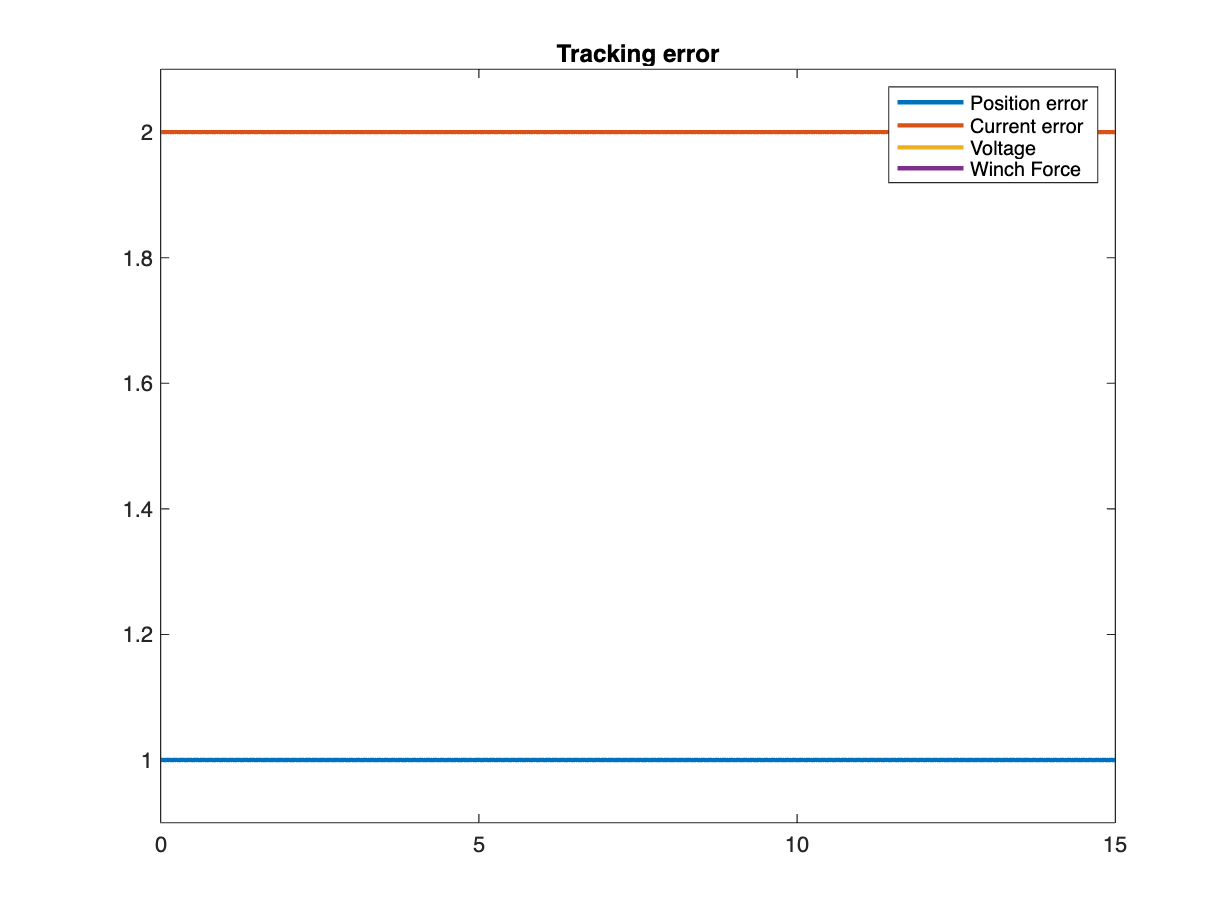

[y2, t2] = lsim(CL2, ref, t);
figure()
plot(t2, y2(:,1),t2, y2(:,2),t2, y2(:,3),t2, y2(:,4),'LineWidth',2)
ylim([0.9,2.1])
title("Tracking error")
legend("Position error",'Current error','Voltage','Winch Force')

Simulation results show null

# CASE III: No scaling, hinfsyn(...) on Pe with performance weights $w_s\ e\ w_u$ 

Let's now add performance weights for the sensitivities, with no scaling.

$P_e =\left\lbrack \begin{array}{cc}
w_s  & -w_s G\left(s\right)\\
0 & w_u \\
\cdots \cdots \cdots  & \cdots \cdots \cdots \\
I & -G\left(s\right)
\end{array}\right\rbrack$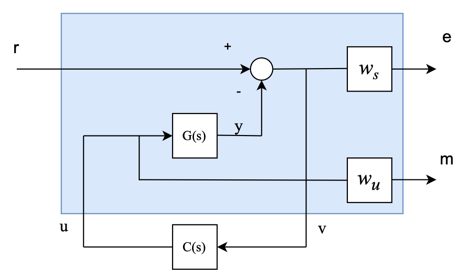

Pe_hinf = [eye(2)*ws -G*ws; zeros(2,2) eye(2)*wu; eye(2) -G];
opts = hinfsynOptions('Method','RIC');

[C3,CL3,gam] = hinfsyn(Pe_hinf,2,2,opts);
gam

gam = 2.4996

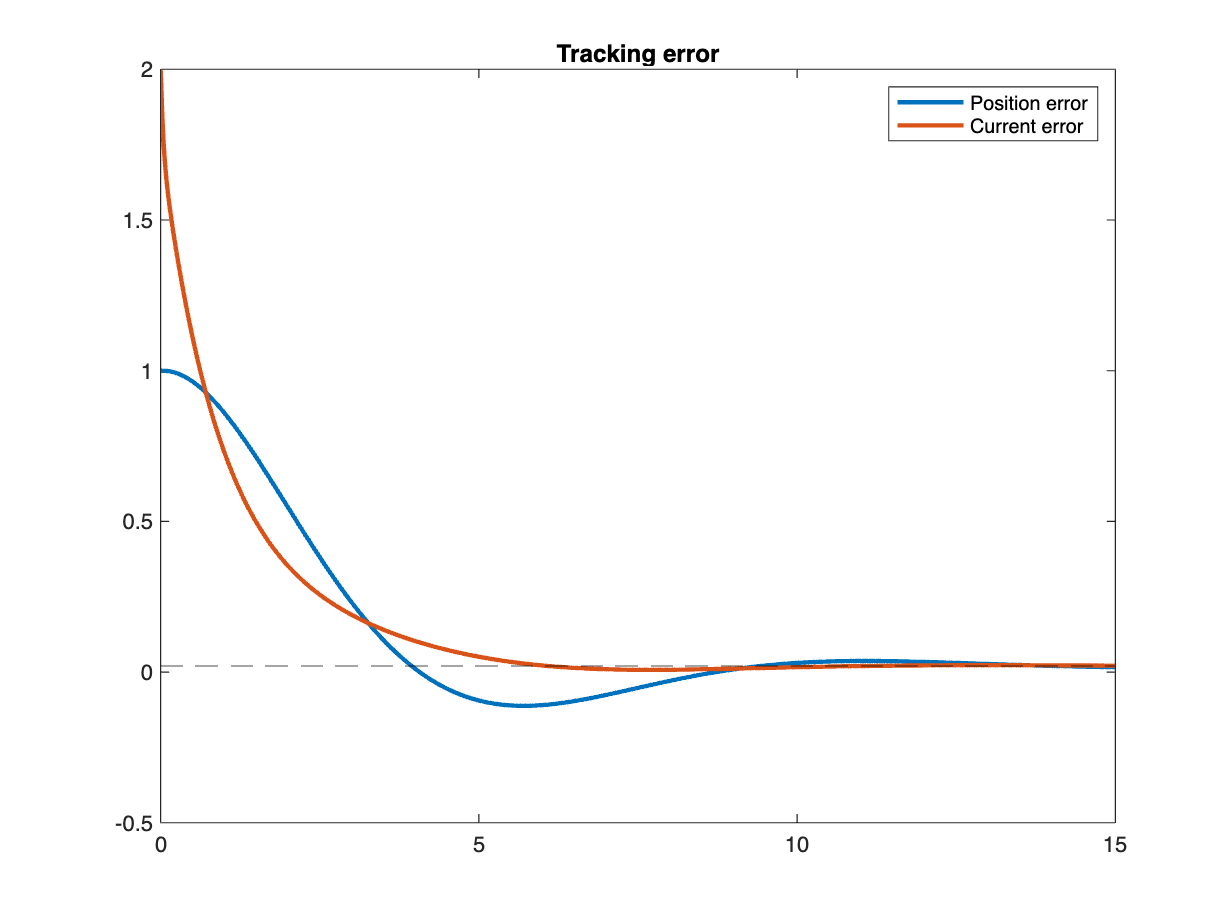

CLoop_hinf = lft(Pe,C3);
[y3, t3] = lsim(CLoop_hinf, ref, t);
figure()
grid on
plot(t3, y3(:,1),t3, y3(:,2),'LineWidth',2)
yline(0.02,'k--')
title("Tracking error")
legend("Position error",'Current error')

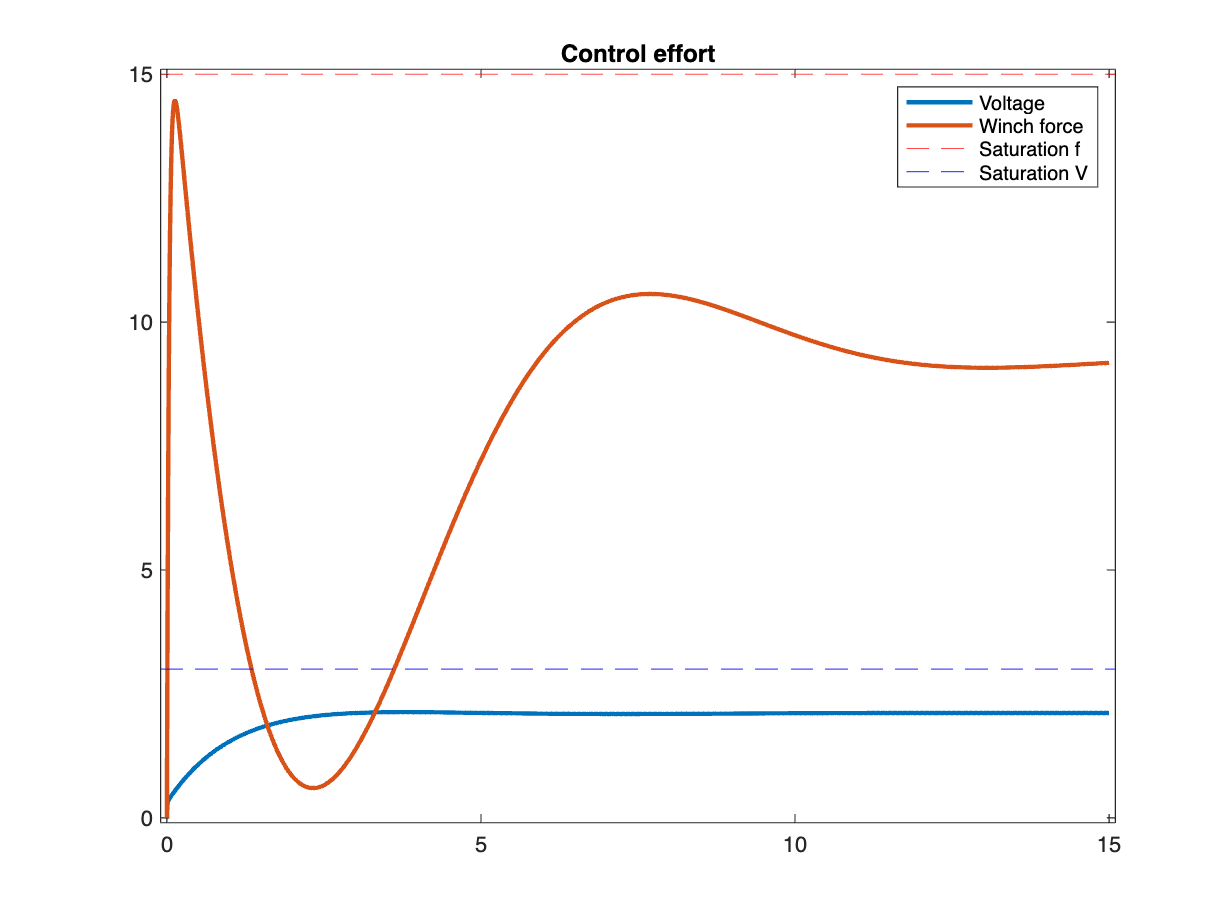

figure()
plot(t3, y3(:,3),t3, y3(:,4),'LineWidth',2)
hold on
yline(15, 'r--')
yline(3, 'b--')
xlim([-0.1,15.1])
ylim([-0.1,15.1])
title("Control effort")
legend('Voltage','Winch force','Saturation f','Saturation V','Location','northeast')

We obtain the same result as the mixsyn one, to the point where the difference between output vectors is approximable to zero.

norm(y3-y_uns)

ans = 1.1494e-05

This result is not surprising since we built the exact same augmented plant that mixsyn builds implicitly.

# CASE IV: Scaling $[u, e_y, r]$  with no performance weights

Let's check if hinfsyn can work with scaling and no performance weights. As a first step, let's scale w.r.t. u.

We know that for the actuation limits (DC motor and winch), u1 can't exceed 3 V and u2 15 N.  Hence, our **input** **scaling matrix is** $D_u =\left\lbrack \begin{array}{cc}
3 & 0\\
0 & 15
\end{array}\right\rbrack ;$

Let's then scale everything w.r.t. tracking error, that in the initial instants equals the reference. The **tracking error scaling matrix ** is $D_e =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right\rbrack ;$

Now we can **scale the reference **in a similar fashion $D_e :D_r =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 2
\end{array}\right\rbrack$; And thefine the quantities ${\;D}_e^{-1} =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 0\ldotp 5
\end{array}\right\rbrack ;\;\;R={\;D}_e^{-1} D_r =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \;\;$

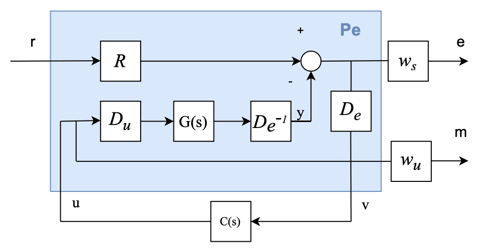

**For the moment, let's consider the performance weights as identities** and build the augmented plant with connect().

%Plant I/O
G.u = 'u_unsc'; G.y = 'y_unsc';

% Scale inputs
wu1 = 3; wu2 = 15;
Du = tf([wu1 0; ...
        0 wu2]);
Du.u = 'u'; Du.y = 'u_unsc';

% Scale Reference
wr1 = 1; wr2 = 2;
Dr = tf([wr1 0; 0 wr2]);
Dr.u = 'r'; Dr.y = 'r_bar';

% Scale error
we1 = 1; we2 = 2;
De = tf([we1 0; 0 we2]);
De.u = 'e_bar'; De.y = 'v';

De_inv = tf([1/we1 0; 0 1/we2]);
De_inv.u = 'y_unsc'; De_inv.y = 'y_bar';

% Error sum link
Sum = sumblk('e_bar = r_bar - y_bar', 2);

Pe3 = connect(G, Du, Dr, De, De_inv, Sum,{'r','u'},{'e_bar','u','v'});

[C4,CL4,gam] = hinfsyn(Pe3,2,2);
gam

gam = 2.0000

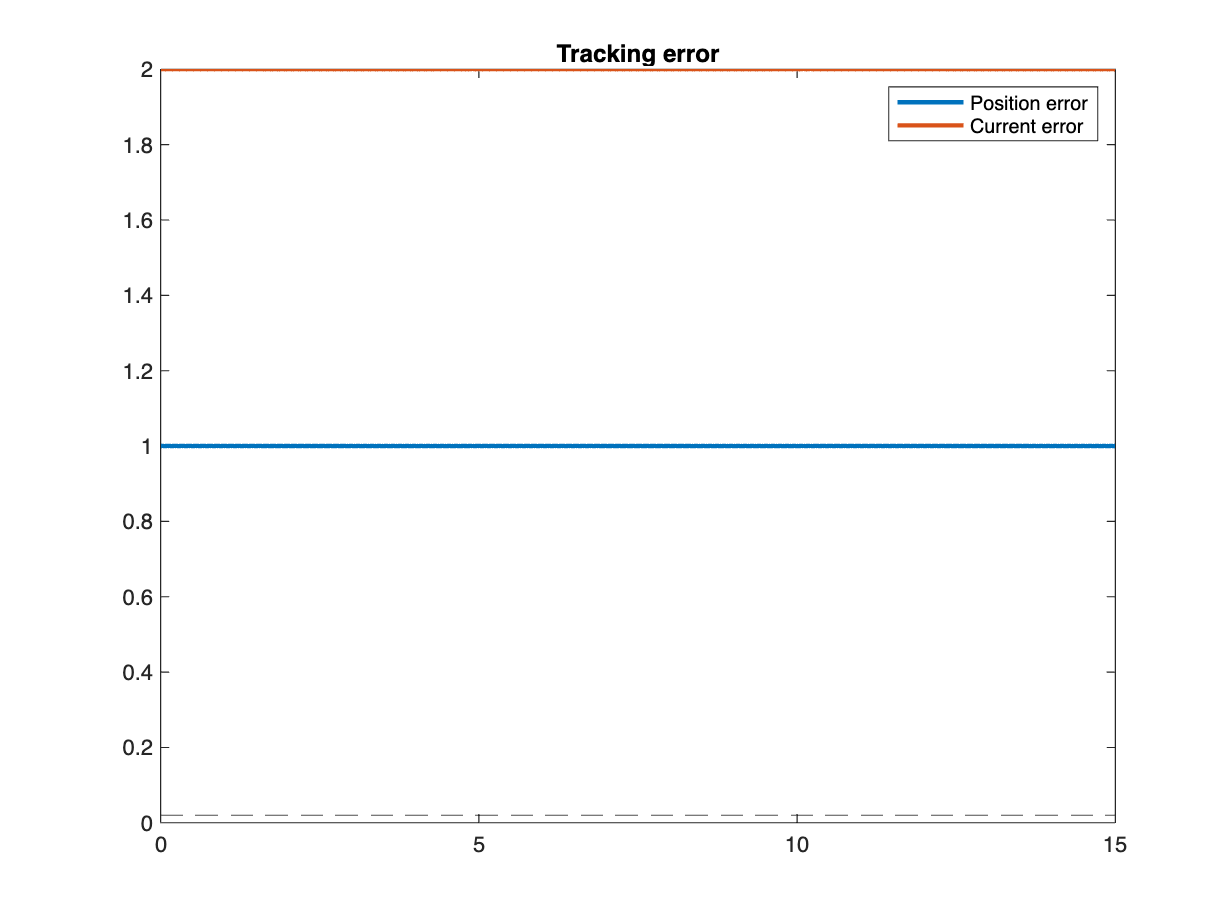

CLoop4 = lft(Pe,C4);
[y4, t4] = lsim(CLoop4, ref, t);
figure()
plot(t4, y4(:,1),t4, y4(:,2),'LineWidth',2)
yline(0.02,'k--')
title("Tracking error")
legend("Position error",'Current error')

Once again if we don't specify performance weights we have a null closed loop system.

# CASE V: scaling and performance weights

Let's try the same scheme as case 4 adding performance weights. Let's also try  different diagonal weights on the performance matrices.

%sensitivity weights
Ms1 = 1.001;
B3s1 = 2.5;
As1 = 0.001;

Ms2 = 1.01;
B3s2 = 1.0;
As2 = 0.01;

Ws1 = (s/Ms1+B3s1)/(s+B3s1*As1);
Ws2 = (s/Ms2+B3s2)/(s+B3s2*As2);

ws = [Ws1 0; 0 Ws2];

ws.u = 'e_bar'; ws.y = 'e_sens';
wu = tf([1/20 0; 0 1/10]); wu.u = 'u'; wu.y = 'u_sens';

Pe4 = connect(G, Du, Dr, De, De_inv, Sum, ws,wu,{'r','u'},{'e_sens','u_sens','v'});
opts = hinfsynOptions('Method','Ric','Autoscale','off','Regularize','off');
[C5,CL5,gam] = hinfsyn(Pe4,2,2);
gam

gam = 1.9975

CLoop5 = lft(Pe,C5);

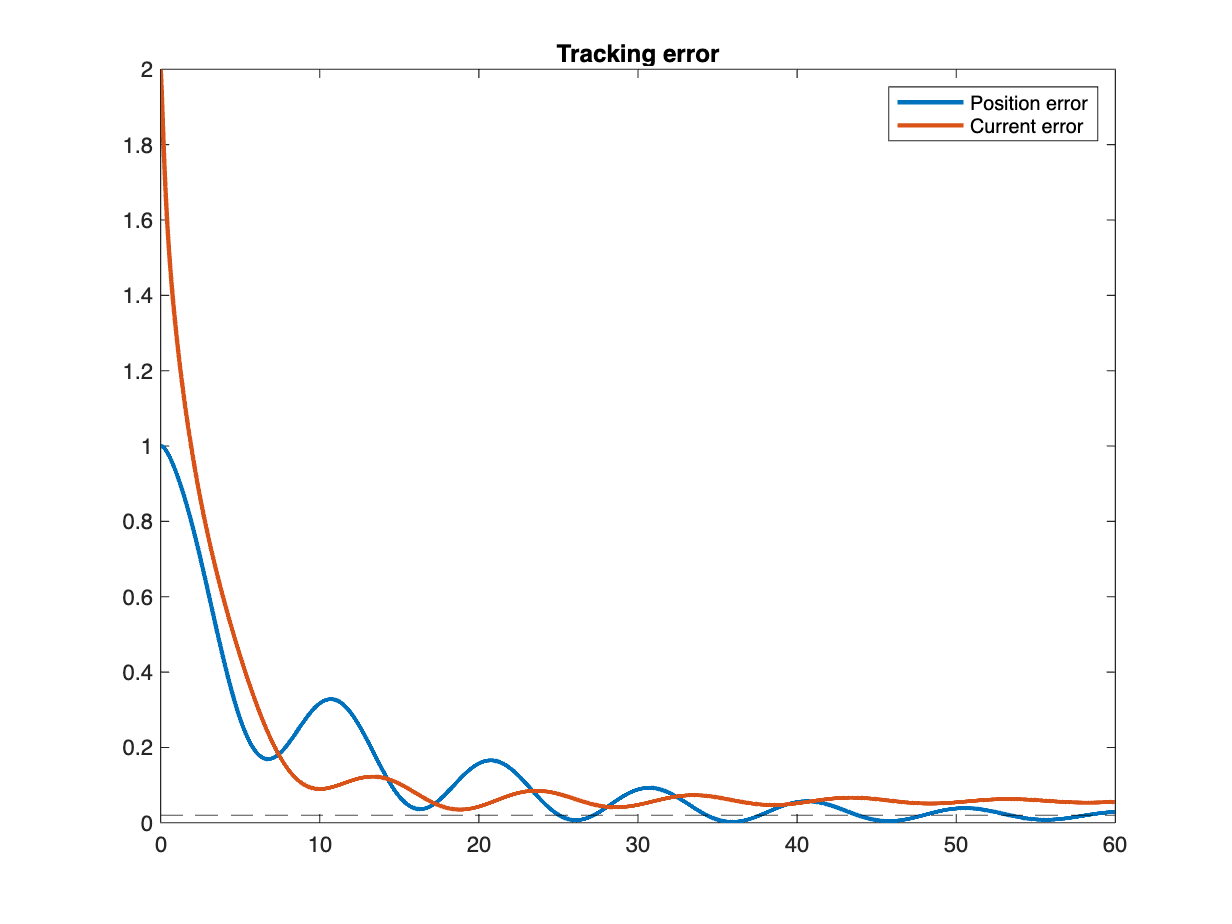

t = 0:0.01:60;
ref = [ones(1,length(t))*r1;
    ones(1,length(t))*r2];

[y5, t5] = lsim(CLoop5, ref, t);
figure()
grid on
plot(t5, y5(:,1),t5, y5(:,2),'LineWidth',2)
yline(0.02,'k--')
title("Tracking error")
legend("Position error",'Current error')

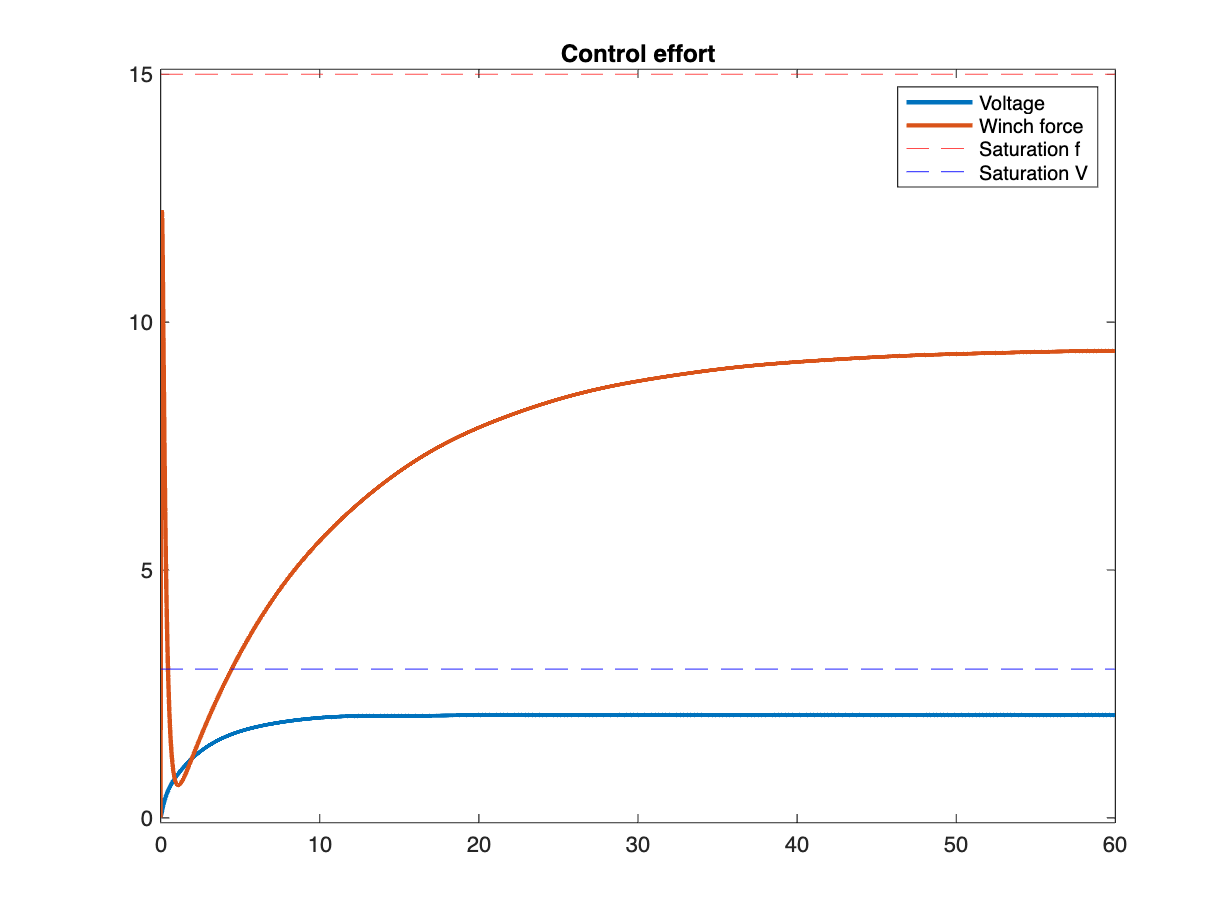

figure()
plot(t5, y5(:,3),t5, y5(:,4),'LineWidth',2)
hold on
yline(15, 'r--')
yline(3, 'b--')
ylim([-0.1,15.1])
title("Control effort")
legend('Voltage','Winch force','Saturation f','Saturation V','Location','northeast')

Running countless tests, even using the solution algorithm LMI in the H-infinity options and a gamTry > 0, the achieved performance is stll significantly worse than in the uscaled version. Convergence time is up to 6 times slower and oscillations are much more prominent ..